% priprava podatkov
clear all;
data = load('VAJA3.mat');

% Priprava podatkov
A_FLOW = data.A_FLOW;
T_H2O = data.T_H2O;
C_ACID = data.C_ACID;
I_EFF = data.I_EFF;
X = [A_FLOW, T_H2O, C_ACID];
Y = I_EFF;

% Izbira standardizacijskih metod
standardization_methods = ["min-max", "z-score", "nonec"];


    "LSE Standardization Method: "    "a"



Regression Coefficients: 0.715640 1.295286 -0.152123 -39.919674


parameter variance: 0.018187 0.135442 0.024428 141.514741


Normalized Root Mean Squared Error (NRMSE):  0.287


Error Variance: 8.941, Error Bias: 0.000, Error Standard deviation: 2.990


    "LSE Standardization Method: "    "b"



Regression Coefficients: 0.715640 1.295286 -0.152123 -39.919674


parameter variance: 0.018187 0.135442 0.024428 141.514741


Normalized Root Mean Squared Error (NRMSE):  0.287


Error Variance: 8.941, Error Bias: 0.000, Error Standard deviation: 2.990


    "LSE Standardization Method: "    "c"



Regression Coefficients: 0.715640 1.295286 -0.152123 -39.919674


parameter variance: 0.018187 0.135442 0.024428 141.514741


Normalized Root Mean Squared Error (NRMSE):  0.287


Error Variance: 8.941, Error Bias: 0.000, Error Standard deviation: 2.990


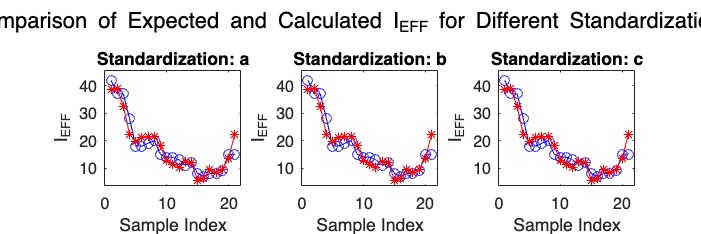



% Zanka za LSE
for i = 1:length(standardization_methods)
    n = standardization_methods(i);
    
    % Standardizacija podatkov
    [X_n, Y_n] = abc(X, Y, n);
    
    % Dodajanje stolpca enic za presledek
    X_n = [X_n, ones(size(X_n, 1), 1)];
    X_c = [X, ones(size(X, 1), 1)];

    % Izračun parametrov beta z metodo LSE
    beta_hat_std = (X_n' * X_n) \ (X_n' * Y_n);

    % Transformacija parametrov nazaj v originalni prostor, če je potrebno
    if n == "a"
        min_X = min(X);
        max_X = max(X);
        min_Y = min(Y);
        max_Y = max(Y);

        beta_hat_X = beta_hat_std(1:end-1)' .* (max_Y - min_Y) ./ (max_X - min_X);
        beta_hat_0 = beta_hat_std(end) * (max_Y - min_Y) + min_Y - sum(beta_hat_X .* min_X);
        beta_hat = [beta_hat_X, beta_hat_0];

        % Izračun predvidenih vrednosti I_EFF
        I_EFF_pred = X_c * beta_hat';

    elseif n == "b"
        mu_X = mean(X);
        sigma_X = std(X);
        mu_Y = mean(Y);
        sigma_Y = std(Y);

        beta_hat_X = beta_hat_std(1:end-1)' .* sigma_Y ./ sigma_X;
        beta_hat_0 = beta_hat_std(end) * sigma_Y + mu_Y - sum(beta_hat_X .* mu_X);
        beta_hat = [beta_hat_X, beta_hat_0];

        % Izračun predvidenih vrednosti I_EFF
        I_EFF_pred = X_c * beta_hat';
    elseif n == "c"
        beta_hat = beta_hat_std';
        I_EFF_pred = X_c * beta_hat';
    end

    % Izračun napake, kovariančne matrike in NRMSE
    error_LSE = I_EFF - I_EFF_pred;
    cov_matrix_LSE = pinv(X_c' * X_c) * (error_LSE' * error_LSE) / (size(X_c, 1) - size(X_c, 2));
    NRMSE_LSE = sqrt(sum((error_LSE).^2) / (size(X, 1))) / std(Y);
    STD_LSE = std(error_LSE);

    % Prikaz rezultatov
    disp(['LSE Standardization Method: ', n]);
    fprintf('Regression Coefficients: %f %f %f %f\n', beta_hat);
    fprintf('parameter variance: %f %f %f %f\n', diag(cov_matrix_LSE));
    fprintf('Normalized Root Mean Squared Error (NRMSE):  %.3f\n', NRMSE_LSE);
    fprintf('Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation: %.3f\n', var(error_LSE), mean(error_LSE), STD_LSE);

    % Prikaz pričakovanih in izračunanih vrednosti
    subplot(1, 3, i);
    plot(1:length(I_EFF), I_EFF, 'bo-', 'DisplayName', 'Expected Y (I_{EFF})');
    hold on;
    plot(1:length(I_EFF), I_EFF_pred, 'r*-', 'DisplayName', 'Calculated Y (I_{EFF_{pred}})');
    xlabel('Sample Index');
    ylabel('I_{EFF}');
    title(sprintf('Standardization: %s', n));
    ylim([min(I_EFF) - 0.1 * range(I_EFF), max(I_EFF) + 0.1 * range(I_EFF)]);
    xlim([0, length(I_EFF) + 1]);
    hold off;
end

    "PCA Standardization Method: "    "a"



Regression Coefficients: 0.798908 1.207175 -0.218784 -37.340803


Normalized Root Mean Squared Error (NRMSE):  0.291


Error Variance: 9.202, Error Bias: -0.000, Error Standard deviation3.033


    "PCA Standardization Method: "    "b"



Regression Coefficients: 0.798827 1.213428 -0.215911 -37.715639


Normalized Root Mean Squared Error (NRMSE):  0.291


Error Variance: 9.207, Error Bias: 0.000, Error Standard deviation3.034


    "PCA Standardization Method: "    "c"



Regression Coefficients: 0.407372 2.503537 -0.179182 -44.444982


Normalized Root Mean Squared Error (NRMSE):  0.367


Error Variance: 14.634, Error Bias: -0.000, Error Standard deviation3.825


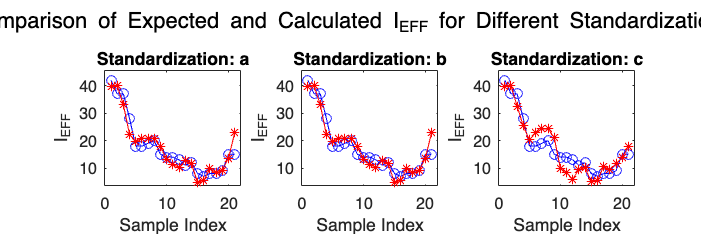

% PCA del kode
figure;
for i = 1:length(standardization_methods)
    n = standardization_methods(i);
    
    %% PCA Regression
    % Standardizacija podatkov
    [X_n, Y_n] = abc(X, Y, n);

    % Kombinacija in centriranje podatkov
    Z = [X_n, Y_n];
    nn = size(Z, 1);
    Z_centered = Z - mean(Z);

    % Izračun kovariančne matrike
    F = (Z_centered' * Z_centered) / (nn - 1);

    % Izračun singularne vrednosti dekompozicije
    [P, D] = svd(F);

    % Pridobitev koeficientov prve glavne komponente
    coeff = P(:, end);

    % Izračun eksplicitnih koeficientov modela
    if n == "a" 
        a = coeff(1:end-1)' ./ coeff(end);
        c = -a .* (max(Y) - min(Y)) ./ (max(X) - min(X));
        d = sum(a .* (mean(X_n) .* (max(Y) - min(Y)))) + mean(Y_n) * (max(Y) - min(Y)) + min(Y) + (max(Y) - min(Y)) .* a ./ (max(X) - min(X)) * min(X)';
    elseif n == "b"
        a = coeff(1:end-1)' ./ coeff(end);
        c = -a .* std(Y) ./ std(X);
        d = sum(a .* (mean(X_n) .* std(Y))) + mean(Y_n) * std(Y) + mean(Y) + std(Y) .* a ./ std(X) * mean(X)';
    else
        c = -coeff(1:end-1)' ./ coeff(end);
        d = mean(Y_n) - sum(c .* mean(X_n));
    end

    model_PCA_poly = [c d];

    % Izračun predvidenih vrednosti I_EFF
    model_PCA = sum(model_PCA_poly .* horzcat(X, ones(size(X, 1), 1)), 2);

    % Izračun napake in NRMSE
    error_PCA = I_EFF - model_PCA;
    NRMSE_PCA = sqrt(sum((error_PCA).^2) / (size(X, 1))) / std(Y);
    STD_PCA = std(error_PCA);

    % Prikaz rezultatov
    disp(['PCA Standardization Method: ', n]);
    fprintf('Regression Coefficients: %f %f %f %f\n', model_PCA_poly);
    fprintf('Normalized Root Mean Squared Error (NRMSE):  %.3f\n', NRMSE_PCA);
    fprintf('Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation%.3f\n', var(error_PCA), mean(error_PCA), STD_PCA);

    % Prikaz pričakovanih in izračunanih vrednosti
    subplot(1, 3, i);
    plot(1:length(I_EFF), I_EFF, 'bo-', 'DisplayName', 'Expected Y (I_{EFF})');
    hold on;
    plot(1:length(I_EFF), model_PCA, 'r*-', 'DisplayName', 'Calculated Y (I_{EFF_{pred}})');
    xlabel('Sample Index');
    ylabel('I_{EFF}');
    title(sprintf('Standardization: %s', n));
    ylim([min(I_EFF) - 0.1 * range(I_EFF), max(I_EFF) + 0.1 * range(I_EFF)]);
    xlim([0, length(I_EFF) + 1]);
    hold off;
end


% KOLINEARNOST
% Inicializacija shranjevanja parametrov
M = 100;
params_LSE = zeros(M, 4);
params_PCR = zeros(M, 4);

for i = 1:M
    % Dodajanje nove meritve z šumom
    X_additional = 2 * T_H2O + 6 + 0.1 * randn(size(T_H2O, 1), 1);
    X = [A_FLOW, T_H2O, C_ACID, X_additional];
    Y = I_EFF;
    [X_n, Y_n] = abc(X, Y, "b");

    %% LSE
    theta_LSE = (X_n' * X_n) \ (X_n' * Y_n);
    params_LSE(i, :) = theta_LSE';

    %% PCR
    % Kombinacija in centriranje podatkov
    Z = [X_n];
    nn = size(Z, 1);
    Z_centered = Z - mean(Z);

    % Izračun kovariančne matrike
    F = (Z_centered' * Z_centered) / (nn - 1);

    % Izvedba SVD
    [P, D] = svd(F);

    % Odstranjevanje glavne komponente z neznatnim vplivom (zadnja komponenta)
    P_reduced = P(:, 1:end-1);

    % Transformacija originalnih podatkov v prostor glavnih komponent
    T = X_n * P_reduced;

    % Izračun parametrov v prostoru glavnih komponent
    theta_PCR_reduced = (T' * T) \ (T' * Y_n);

    % Transformacija parametrov nazaj v originalni prostor
    theta_PCR = P_reduced * theta_PCR_reduced;
    params_PCR(i, :) = theta_PCR';
end

% Povprečje vseh iteracij
theta_LSE = mean(params_LSE)';
theta_PCR = mean(params_PCR)';

% Izračun napovedanih vrednosti in napak
y_pred_LSE = X_n * theta_LSE;
y_pred_PCR = X_n * theta_PCR;

error_LSE = y_pred_LSE - Y_n;
error_PCR = y_pred_PCR - Y_n;

NRMSE_LSE = sqrt(sum((error_LSE).^2) / size(X_n, 1)) / std(Y_n);
NRMSE_PCR = sqrt(sum((error_PCR).^2) / size(X_n, 1)) / std(Y_n);

% Teoretične variacije za LSE
cov_matrix_LSE = pinv(X_n' * X_n) * (error_LSE' * error_LSE) / (size(X_n, 1) - size(X_n, 2));

% Rezultati LSE
fprintf('LSE parameters: %f %f %f %f\n', theta_LSE);
fprintf('LSE experimental parameters variations: %f %f %f %f\n', var(params_LSE));
fprintf('LSE theoretical parameters variations: %f %f %f %f\n', diag(cov_matrix_LSE));
fprintf('LSE Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation: %.3f\n', var(error_LSE), mean(error_LSE), std(error_LSE));
fprintf('LSE NEMSE:  %.3f\n', NRMSE_LSE);

% Rezultati PCR
fprintf('PCR parameters: %f %f %f %f\n', theta_PCR);
fprintf('PCR experimental parameters variations: %f %f %f %f\n', var(params_PCR));
fprintf('PCR Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation: %.3f\n', var(error_PCR), mean(error_PCR), std(error_PCR));
fprintf('PCR NEMSE:  %.3f\n', NRMSE_PCR);

% Prikaz rezultatov
figure;
colors = {'r', 'g', 'b', 'm'};

% Boxploti parametrov LSE
subplot(1,2,1);
boxplot(params_LSE, 'Colors', cell2mat(colors), 'Symbol', '+');
title('Boxplot of LSE Parameters');
xlabel('Parameters');
ylabel('Parameter Values');

% Prikaz vrednosti theta_LSE nad boxploti
hold on;
for i = 1:length(theta_LSE)
    text(i, max(params_LSE(:,i)) + 2, sprintf('%.4f', theta_LSE(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', colors{i}, 'FontSize', 12, 'FontWeight', 'bold');
end
hold off;

% Boxploti parametrov PCR
subplot(1,2,2);
boxplot(params_PCR, 'Colors', cell2mat(colors), 'Symbol', '+');
title('Boxplot of PCR Parameters');
xlabel('Parameters');
ylabel('Parameter Values');

% Prikaz vrednosti theta_PCR nad boxploti
hold on;
for i = 1:length(theta_PCR)
    text(i, max(params_PCR(:,i)) + 0.02, sprintf('%.4f', theta_PCR(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', colors{i}, 'FontSize', 12, 'FontWeight', 'bold');
end
hold off;

% Prilagoditev postavitve in mej osi
subplot(1,2,1);
ylim([min(min(params_LSE))-5, max(max(params_LSE))+5]);

subplot(1,2,2);
ylim([min(min(params_PCR))-0.1, max(max(params_PCR))+0.1]);

set(gcf, 'Position', [100, 100, 900, 450]);

% Funkcija za standardizacijo podatkov
function [X_n, Y_n] = abc(X,Y,n)
    if n == "a"
        X_n = (X - min(X)) ./ (max(X) - min(X));
        Y_n = (Y - min(Y)) ./ (max(Y) - min(Y));
    elseif n == "b"
        X_n = (X - mean(X)) ./ std(X);
        Y_n = (Y - mean(Y)) ./ std(Y);
    elseif n == "c"
        X_n = X;
        Y_n = Y;
    end
end

% Funkcija za povrnitev standardiziranih podatkov nazaj v originalne vrednosti
function Y_n = abc_rev(Y,n,Y_orig)
    if n == "a"
        Y_n = (Y*(max(Y_orig) - min(Y_orig))) + min(Y_orig);
    elseif n == "b"
        Y_n = (Y .* std(Y_orig)) + mean(Y_orig);
    end
end


LSE Min-Max Model:
y = 0.613406 x1 + 0.370082 x2 + -0.091274 x3 + -0.002018
Param. VAR.: 0.013362 0.011056 0.008794 0.003665
NRMSE: 0.286893
Err. AVG: -0.000000
Err. STD: 0.085435



LSE Z-Score Model:
y = 0.645048 x1 + 0.402502 x2 + -0.080141 x3 + -0.000000
Param. VAR.: 0.014776 0.013079 0.006780 0.004842
NRMSE: 0.286893
Err. AVG: -0.000000
Err. STD: 0.293978



LSE No Standardization Model:
y = 0.715640 x1 + 1.295286 x2 + -0.152123 x3 + -39.919674
Param. VAR.: 0.018187 0.135442 0.024428 141.514741
NRMSE: 0.286893
Err. AVG: 0.000000
Err. STD: 2.990234



PCA Min-Max Model:
y = 0.684778 x1 + 0.344907 x2 + -0.131270 x3 + -0.010690
Param. VAR.: 0.014630 0.012106 0.009628 0.004013
NRMSE: 0.300197
Err. AVG: -0.021380
Err. STD: 0.086671



PCA Z-Score Model:
y = 0.720029 x1 + 0.377065 x2 + -0.113745 x3 + 0.000000
Param. VAR.: 0.015214 0.013467 0.006981 0.004985
NRMSE: 0.291118
Err. AVG: 0.000000
Err. STD: 0.298307



PCA No Standardization Model:
y = 0.407372 x1 + 2.503537 x2 + -0.179182 x3 + 44.444982
Param. VAR.: 16.904584 125.893343 22.705690 131538.092049
NRMSE: 8.746719
Err. AVG: 88.889965
Err. STD: 3.825464

